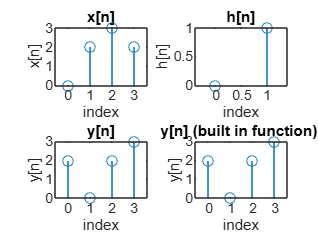

x=input("Enter x[n]:"); 
h=input("Enter h[n]:");
N=max(length(x), length(h));
X=[x,zeros(1,N-length(x))];
H=[h,zeros(1, N-length(h))];
H_new = [H(1),flip(H(2:N),2)];
y = zeros(1,N);
for i=1:N
    y(i) = sum(X.*circshift(H_new, i-1));
end
subplot(221)
stem(0:length(x)-1,x);
xlabel("index");
ylabel("x[n]");
title("x[n]");
subplot(222);
stem(0:length(h)-1,h);
xlabel("index");
ylabel("h[n]");
title("h[n]");
subplot(223);
stem(0:length(y)-1,y);
xlabel("index");
ylabel("y[n]");
title("y[n]");
subplot(224);
stem(0:length(y)-1,cconv(x,h,N));
xlabel("index");
ylabel("y[n]");
title("y[n] (built in function) ");